# Calculate cross section at high field and NI field

## Set atom 

setTestConfig(true)
% atom
atom = Alkali("Lithium7");



## Set cross section simulation for UHF

% B field
uhfB = 2000e-4; %high feshbach field
bField = MagneticField(bias=[0;0;uhfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1);
psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = (5e-12)/3);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

All runs are completed.


## Set cross section simulation for HF

% B field
hfB = 720e-4; %high feshbach field
bField = MagneticField(bias=[0;0;hfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1);
psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

Python Error: ValueError: There is no data available on HFS structure of 2 P 1/2 state
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunction (

All runs are completed.


## Set cross section simulation for NI

% B field
niB = 543.6e-4; %non-inter feshbach field
bField = MagneticField(bias=[0;0;niB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1)

psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

Python Error: OperationalError: no such table: literatureDME
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunction (

All runs are completed.


## Set cross section simulation for LF

% B field
lfB = 100e-4; %non-inter feshbach field
bField = MagneticField(bias=[0;0;lfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1)

psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

All runs are completed.


## Set cross section simulation for NF

% B field
nfB = 10e-4; %non-inter feshbach field
bField = MagneticField(bias=[0;0;nfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1)

psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

Python Error: ValueError: There is no data available on HFS structure of 2 P 1/2 state
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallelFunction (<a href="mat

All runs are completed.


## Set cross section simulation for ZF

% B field
zfB = 0.5e-4; %non-inter feshbach field
bField = MagneticField(bias=[0;0;zfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1)

psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 0;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
All runs are completed.


## Plot

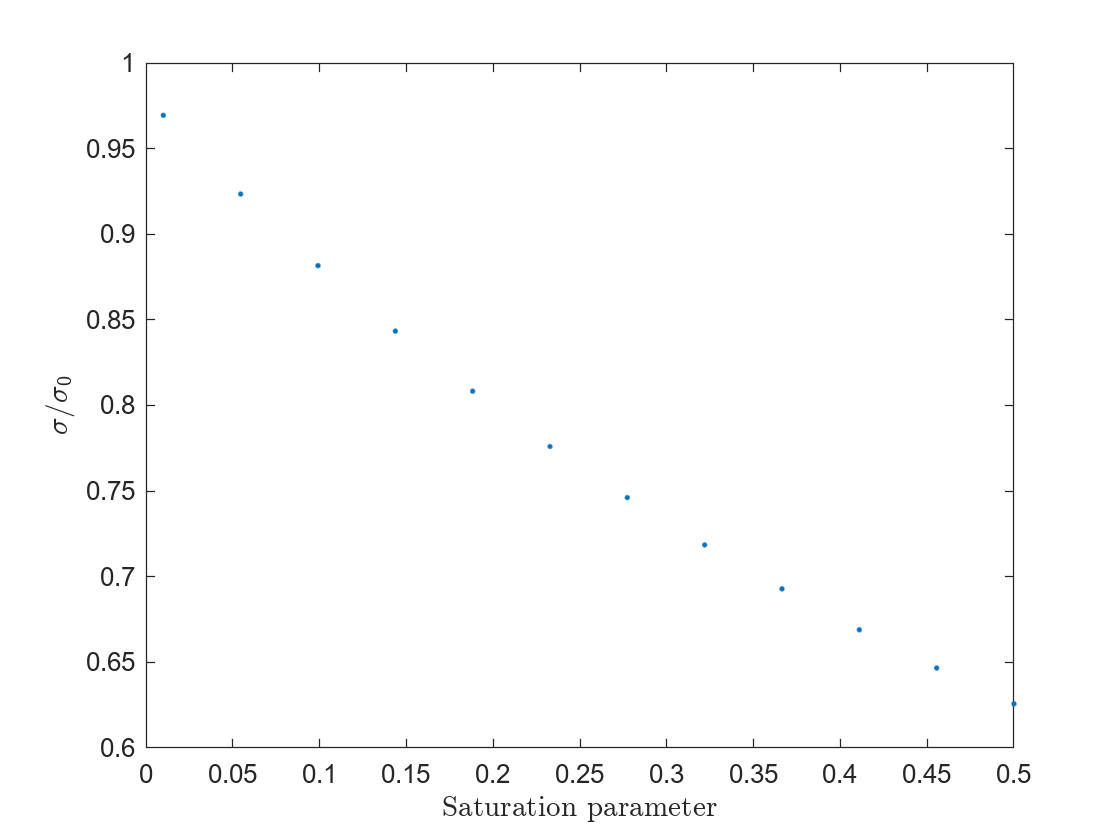


sList0 = 0:0.005:0.5;
sigmaLis1 = 1./(1+sList0);
sigmaLis2 = ones(1,numel(sList0)) / 3;

% plot cross section
trialNumber = 6;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp1,s1] = obj.showCrossSection;

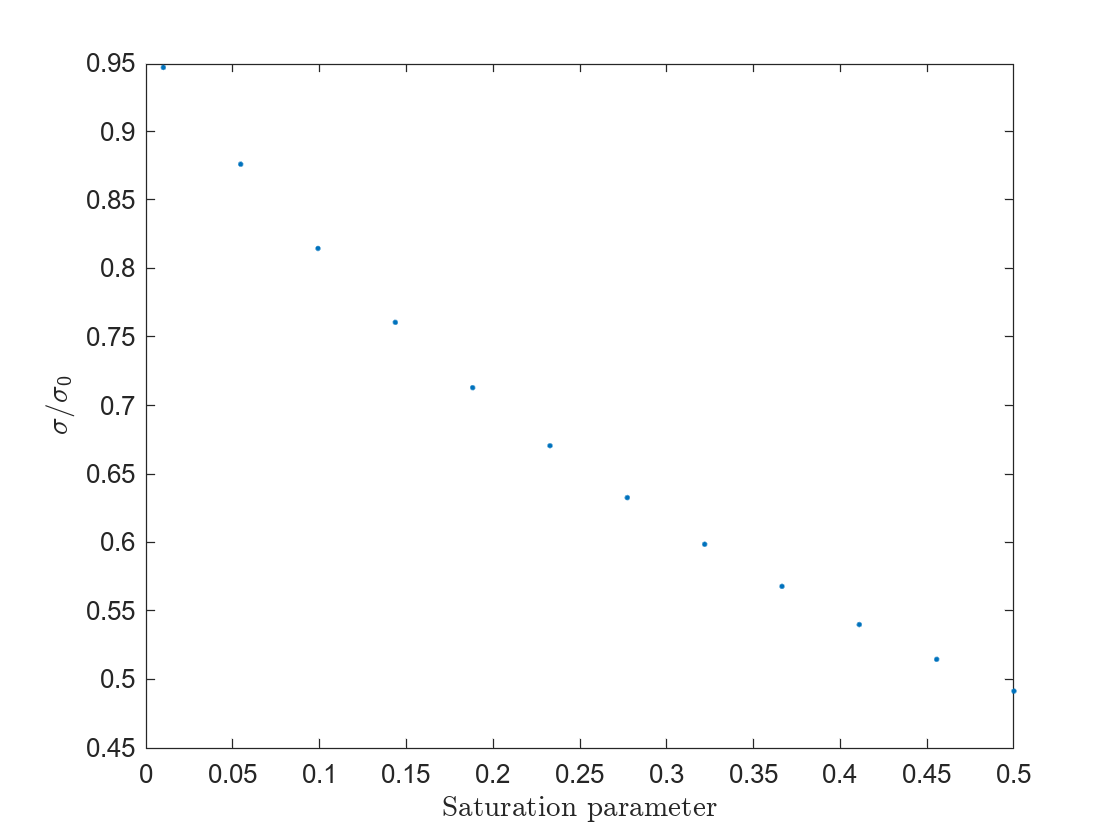


trialNumber = 7;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp2,s2] = obj.showCrossSection;

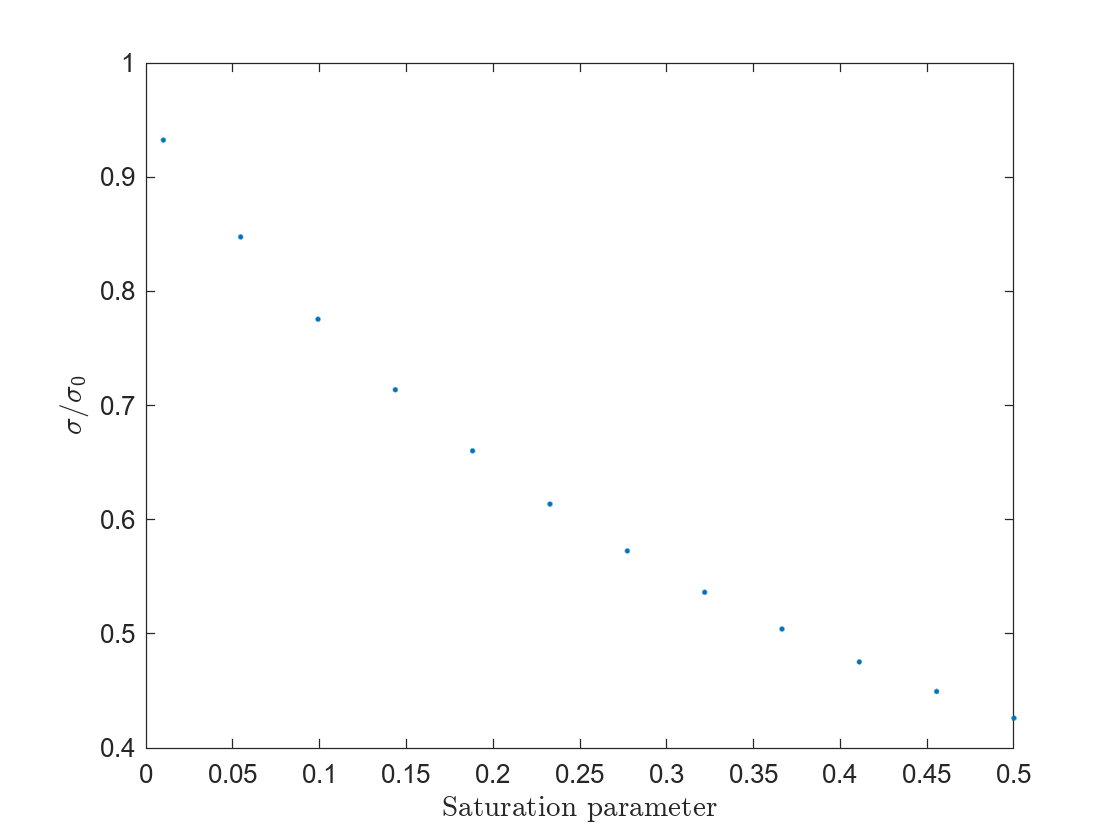


trialNumber = 8;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp3,s3] = obj.showCrossSection;

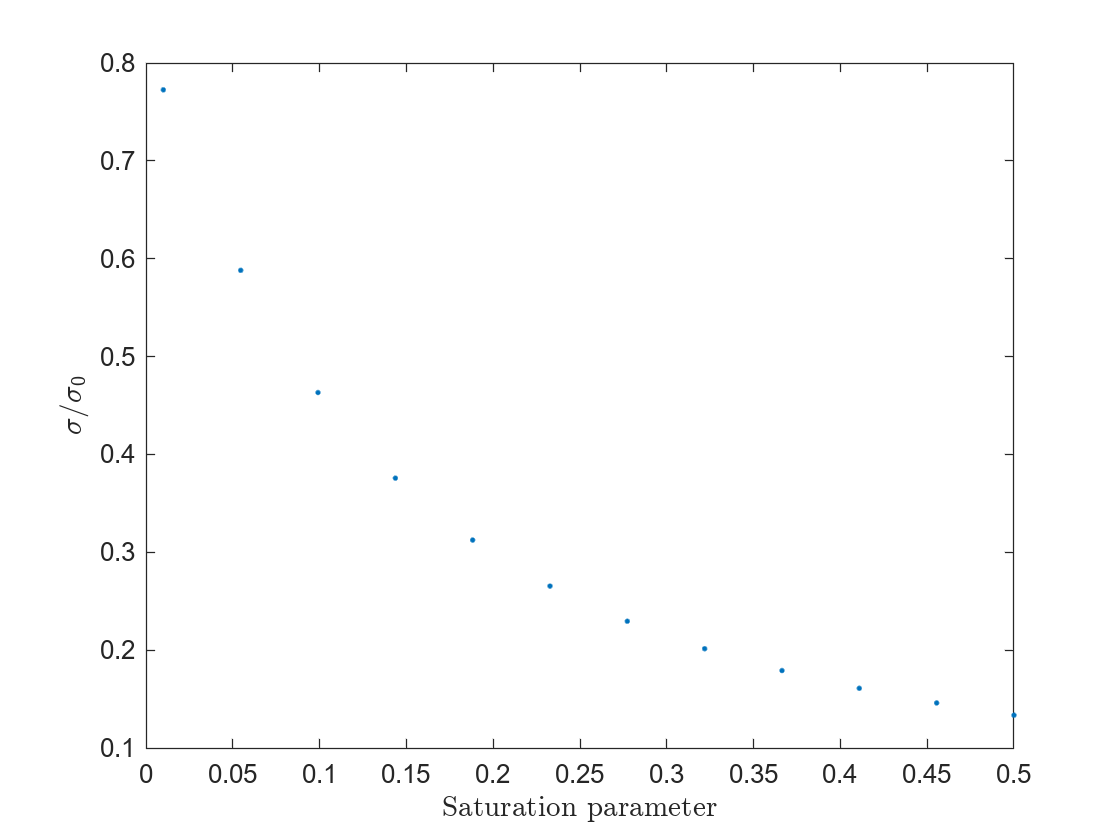


trialNumber = 9;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp4,s4] = obj.showCrossSection;

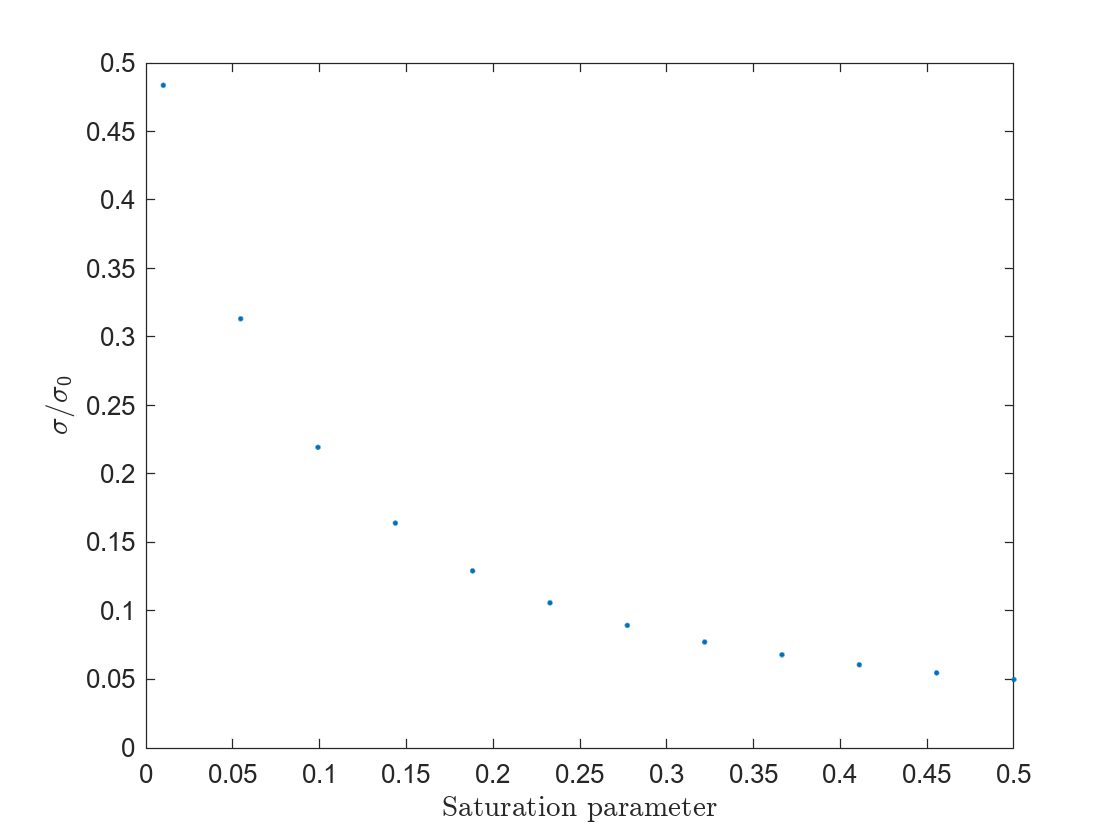


trialNumber = 10;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp5,s5] = obj.showCrossSection;

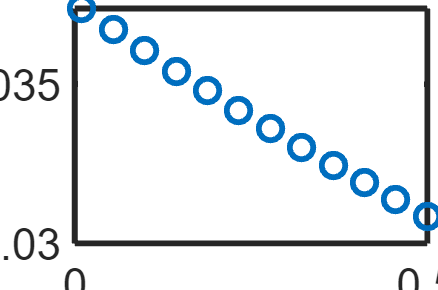


trialNumber = 11;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp6,s6] = obj.showCrossSection;

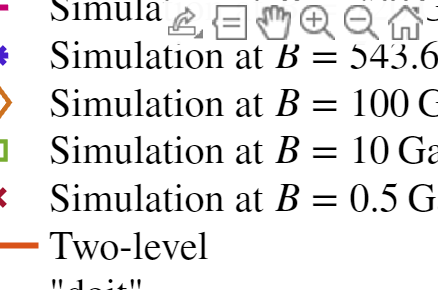


close(figure(2048))
figure(2048)
plot(sp1,s1,'.',sp2,s2,'.',sp3,s3,'.',sp4,s4,'.',sp5,s5,'.',sp6,s6,'.',sList0,sigmaLis1,sList0,sigmaLis2)
legend("Simulation at $B="+num2str(uhfB*1e4)+"~\mathrm{Gauss}$",...
    "Simulation at $B="+num2str(hfB*1e4)+"~\mathrm{Gauss}$",...
    "Simulation at $B="+num2str(niB*1e4)+"~\mathrm{Gauss}$",...
    "Simulation at $B="+num2str(lfB*1e4)+"~\mathrm{Gauss}$",...
    "Simulation at $B="+num2str(nfB*1e4)+"~\mathrm{Gauss}$",...
    "Simulation at $B="+num2str(zfB*1e4)+"~\mathrm{Gauss}$",...
    "Two-level",...
    """doit""",Interpreter="latex")
xlabel("Saturation parameter",Interpreter="latex")
ylabel("$\sigma / \sigma_0$",Interpreter="latex")
render
saveas(gcf,"crossSection.png")

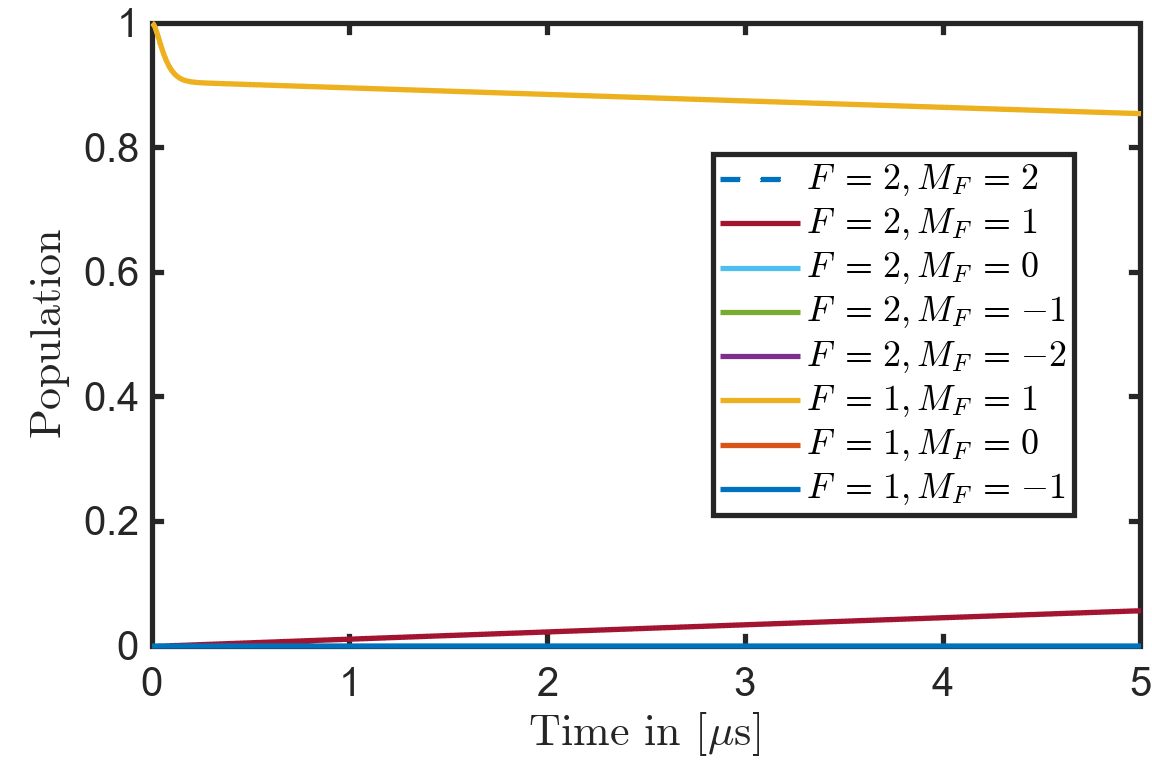

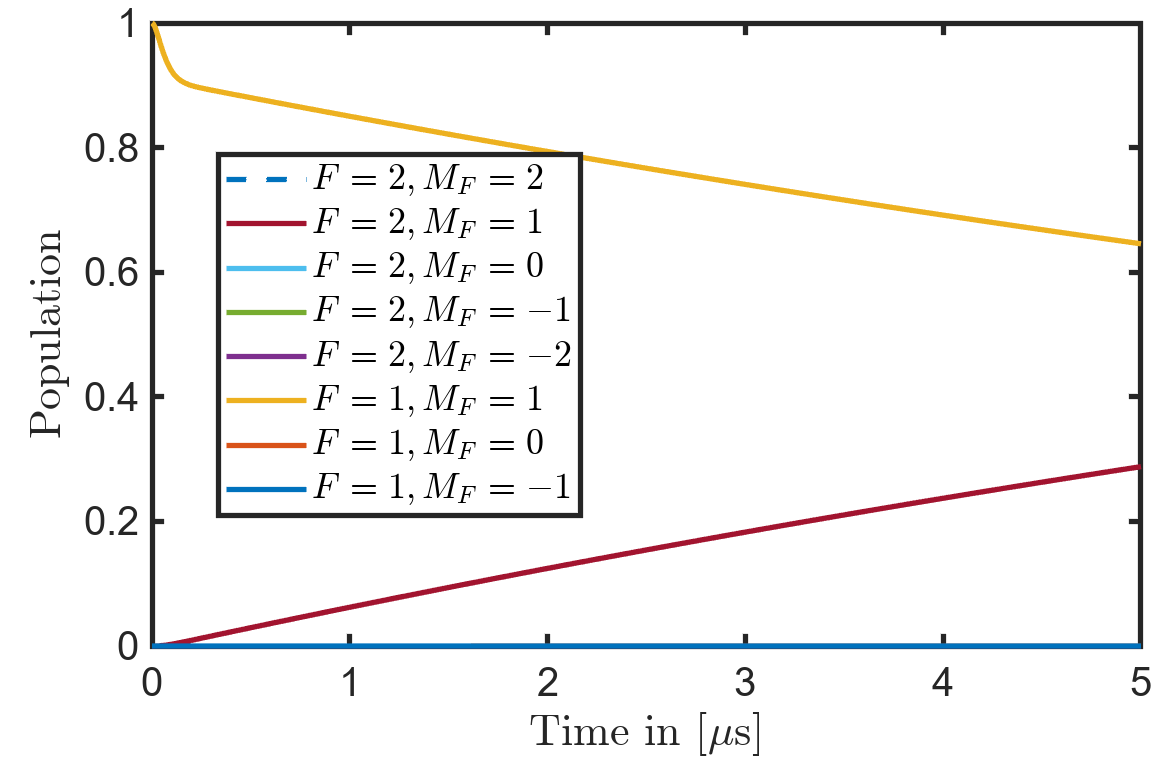

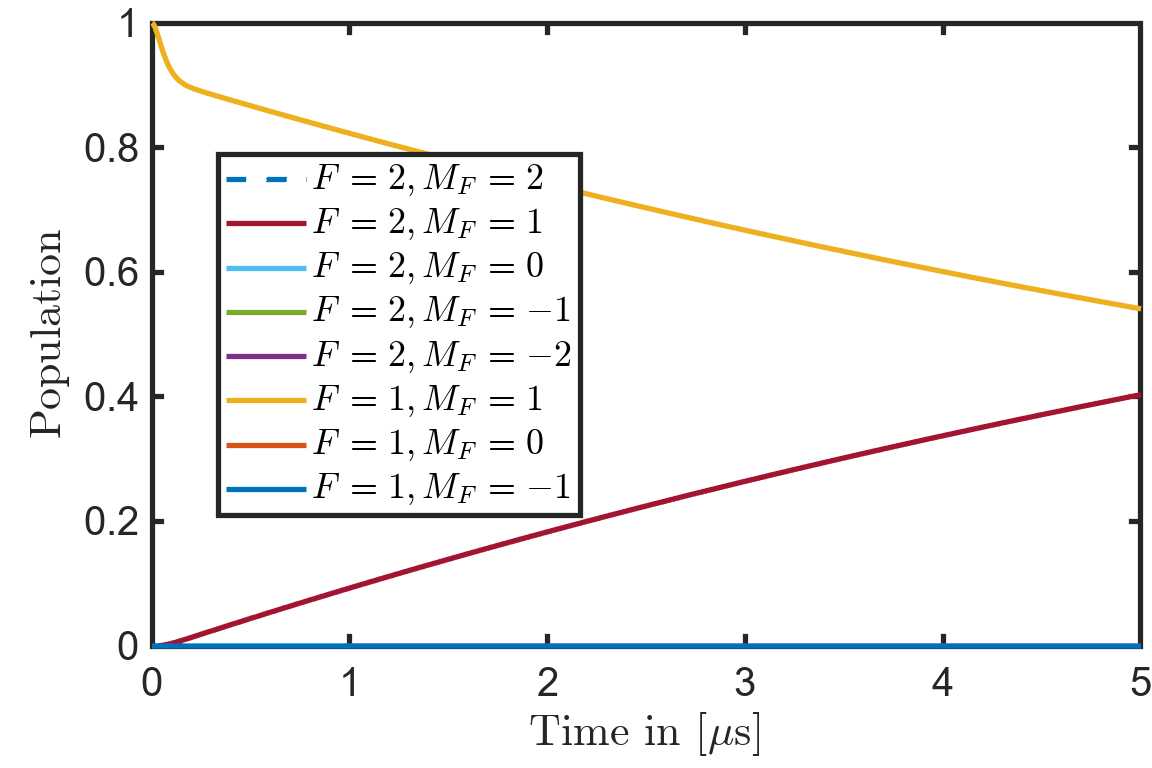

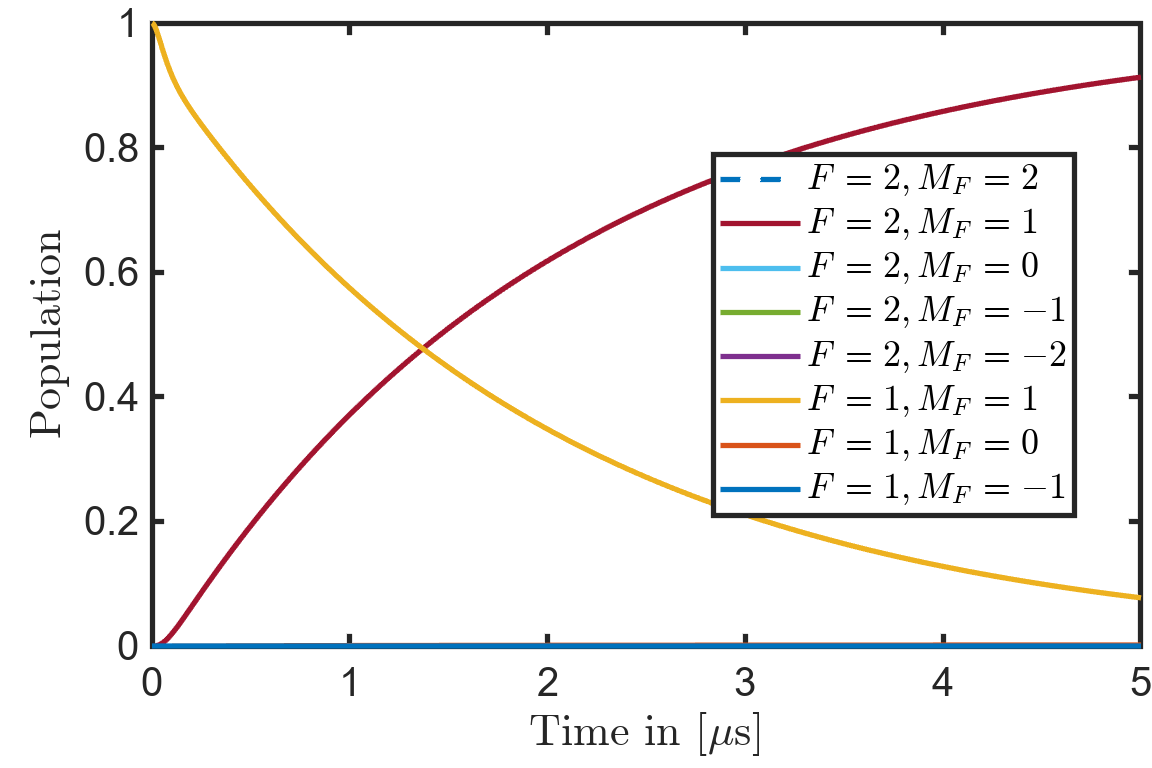

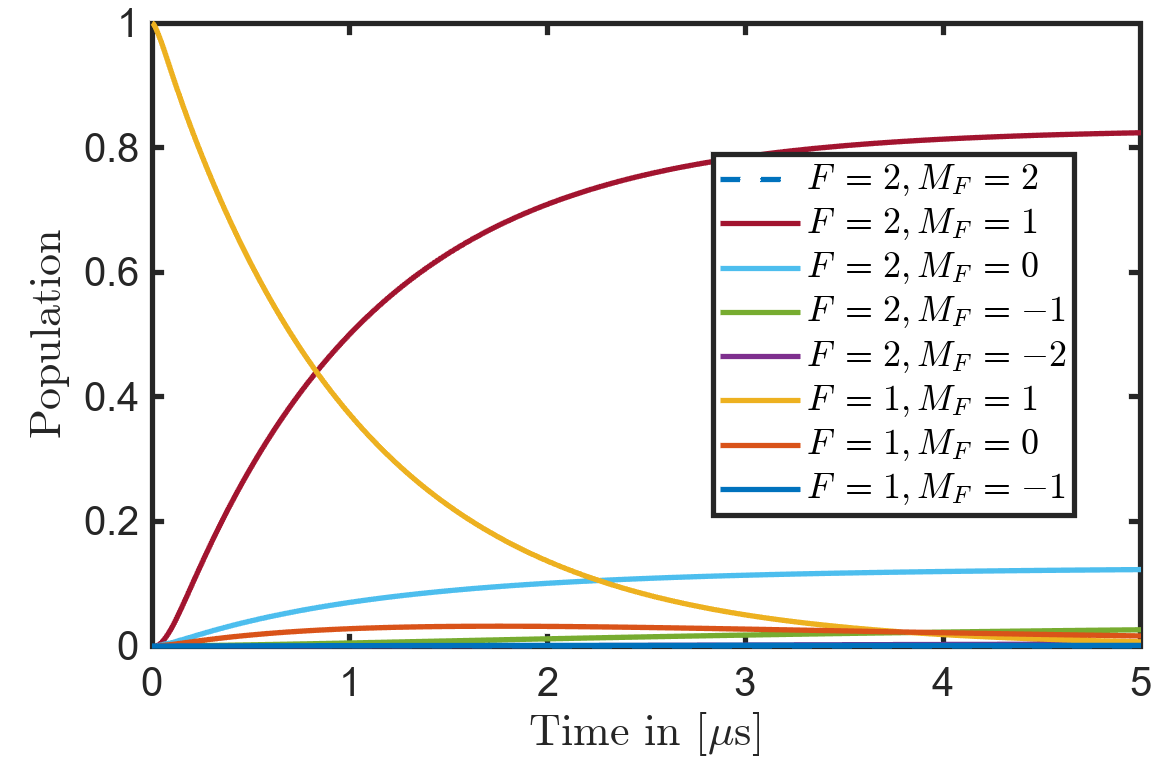

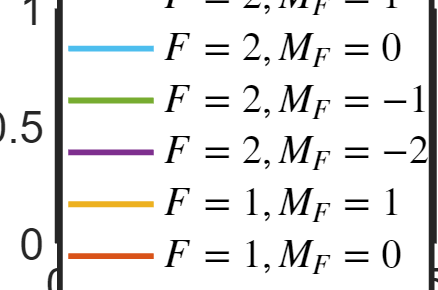


%plot population
for trialNumber = 6:11
    obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
    obj.SimRun(6).showPopulationGround
    saveas(gcf,fullfile(obj.DataAnalysisPath,"popGround.png"),'png')
end